%% 0) Setup
rng(1);
fs = 100; Tsec = 20; t = (0:1/fs:Tsec).'; N = numel(t);
n_traj = 1600;                 % how many trajectories to generate
Tmax   = 130;                  % your safe torque cap
delta_lim = 0.35;              % rad
tau_lo = 0; tau_hi = 0.95*Tmax;

% RANGES (edit here)
rngs.delta.perToneAmp   = [0.03 0.10];       % rad
rngs.delta.totalAmpCap  = 0.35;              % rad
rngs.delta.freqHz       = [0.08 1.20];       % Hz
rngs.delta.const        = [0.05 0.20];       % rad (circle)
rngs.delta.ditherRMS    = [0.003 0.010];     % rad
rngs.delta.fish.step    = [0.15 0.35];       % rad
rngs.delta.fish.rise    = [0.2 0.6];         % s
rngs.delta.fish.delay   = [0.5 1.5];         % s

rngs.tau.biasFrac       = [0.30 0.85];       % ×Tmax
rngs.tau.perToneFrac    = [0.03 0.10];       % ×Tmax
rngs.tau.totalFracCap   = 0.25;              % ×Tmax
rngs.tau.freqHz         = [0.05 1.00];       % Hz
rngs.tau.ditherFracRMS  = [0.01 0.05];       % ×Tmax
rngs.tau.prbs.level     = [0.05 0.25];       % ×Tmax
rngs.tau.prbs.dwell     = [0.15 0.50];       % s
rngs.tau.ramp.slope     = [0.02 0.10];       % ×Tmax per second
rngs.tau.ramp.segDur    = [3.0  8.0];        % s
rngs.tau.chirp.freq     = [0.05 1.50];       % Hz
rngs.tau.chirp.ampFrac  = [0.05 0.20];       % ×Tmax

tones.delta = 4 + randi(2);   % 4–6 tones steering
tones.tau   = 4 + randi(2);   % 4–6 tones torque

% Preallocate
DELTA = zeros(N, n_traj);
TAU   = zeros(N, n_traj);

%% 1) Make frequency pools once; enforce disjoint sets per trajectory
% (log-spaced to cover decades fairly)
Fd_pool = 2*pi*logspace(log10(2*pi*rngs.delta.freqHz(1)), log10(2*pi*rngs.delta.freqHz(2)), 40);
Ft_pool = 2*pi*logspace(log10(2*pi*rngs.tau.freqHz(1)),   log10(2*pi*rngs.tau.freqHz(2)),   40);

%% 2) Generate trajectories
patterns_delta = ["straight","slalom","fishhook","circle","multisine"];
patterns_tau   = ["ramp","multisine","prbs","chirp"];

for k = 1:n_traj
    % Randomly pick patterns
    pd = patterns_delta(randi(numel(patterns_delta)));
    pt = patterns_tau(randi(numel(patterns_tau)));

    % --- Steering δ(t) ---
    switch pd
    case "straight"
        delta = zeros(N,1);
        delta = delta + randRange(rngs.delta.ditherRMS)*randn(N,1);

    case "slalom"
        f = pickTones(Fd_pool, tones.delta);
        a = pickAmps(rngs.delta.perToneAmp, tones.delta, rngs.delta.totalAmpCap);
        phi = 2*pi*rand(1, numel(f));
        delta = multiSine(t, f, a, phi);
        delta = saturate(delta + randRange(rngs.delta.ditherRMS)*randn(N,1), delta_lim);

    case "fishhook"
        A = randRange(rngs.delta.fish.step) * sign(randn);
        rise = randRange(rngs.delta.fish.rise);
        delay = randRange(rngs.delta.fish.delay);
        t1 = Tsec/2 - delay/2; t2 = t1 + delay;   % center the hook roughly
        delta = fishhookSignal(t, A, rise, t1, t2);
        delta = saturate(delta + randRange(rngs.delta.ditherRMS)*randn(N,1), delta_lim);

    case "circle"
        A = randRange(rngs.delta.const) * sign(randn);
        delta = A*ones(N,1) + randRange(rngs.delta.ditherRMS)*randn(N,1);
        delta = saturate(delta, delta_lim);

    case "multisine"
        f = pickTones(Fd_pool, tones.delta);
        a = pickAmps(rngs.delta.perToneAmp, tones.delta, rngs.delta.totalAmpCap);
        phi = 2*pi*rand(1, numel(f));
        delta = multiSine(t, f, a, phi);
        delta = saturate(delta + randRange(rngs.delta.ditherRMS)*randn(N,1), delta_lim);
    end

    % --- Torque τ(t) ---  (choose frequency set disjoint from δ's if multisine/chirp)
    switch pt
    case "ramp"
        bias = randRange(rngs.tau.biasFrac)*Tmax;
        [tau, ~] = rampAccelDecel(t, bias, rngs.tau.ramp, Tmax);
        tau = tau + randRange(rngs.tau.ditherFracRMS)*Tmax*randn(N,1);

    case "multisine"
        bias = randRange(rngs.tau.biasFrac)*Tmax;
        f_tau = pickTonesDisjoint(Ft_pool, tones.tau, Fd_pool, tones.delta);  % discourage overlap
        a_tau = pickAmps(rngs.tau.perToneFrac*Tmax, tones.tau, rngs.tau.totalFracCap*Tmax);
        phi = 2*pi*rand(1, numel(f_tau));
        tau = bias + multiSine(t, f_tau, a_tau, phi) + randRange(rngs.tau.ditherFracRMS)*Tmax*randn(N,1);

    case "prbs"
        bias = randRange(rngs.tau.biasFrac)*Tmax;
        lvl  = randRange(rngs.tau.prbs.level)*Tmax;
        dwell = randRange(rngs.tau.prbs.dwell);
        tau = bias + prbsSignal(t, lvl, dwell);
        tau = tau + randRange(rngs.tau.ditherFracRMS)*Tmax*randn(N,1);

    case "chirp"
        bias = randRange(rngs.tau.biasFrac)*Tmax;
        f0 = rngs.tau.chirp.freq(1); f1 = rngs.tau.chirp.freq(2);
        A  = randRange(rngs.tau.chirp.ampFrac)*Tmax;
        tau = bias + chirp(t, 0, Tsec, f1, 'linear')*A;
        tau = tau + randRange(rngs.tau.ditherFracRMS)*Tmax*randn(N,1);
    end

    % Hard limits (time-only, not state-dependent)
    tau = min(max(tau, tau_lo), tau_hi);

    % Store
    DELTA(:,k) = delta;
    TAU(:,k)   = tau;
    traj_name(:,k) = [pd,pt];
end

idx_dstraight = size(find(traj_name(1,:) == 'straight'))

idx_dstraight =      1   325


idx_dcircle = size(find(traj_name(1,:) == 'circle'))

idx_dcircle =      1   302


idx_dfishhook = size(find(traj_name(1,:) == 'fishhook'))

idx_dfishhook =      1   323


idx_dslalom = size(find(traj_name(1,:) == 'slalom'))

idx_dslalom =      1   305


idx_dmultisine = size(find(traj_name(1,:) == 'multisine'))

idx_dmultisine =      1   345


idx_tprbs = size(find(traj_name(2,:) == 'prbs'))

idx_tprbs =      1   387


idx_tramp = size(find(traj_name(2,:) == 'ramp'))

idx_tramp =      1   388


idx_tchirp = size(find(traj_name(2,:) == 'chirp'))

idx_tchirp =      1   402


idx_tmultisine = size(find(traj_name(2,:) == 'multisine'))

idx_tmultisine =      1   423


save("Offroad_InputsSignals","DELTA","traj_name","TAU","idx_tmultisine",...
    "idx_tchirp","idx_tramp","idx_tprbs","idx_dmultisine","idx_dslalom",...
    "idx_dfishhook","idx_dstraight");


%% 3) Quick PE diagnostics on a random subset (Hankel rank on 5 s windows)
nu = 600;                              % past window (tune to your ID plan)
kchk = 1:n_traj;%randperm(n_traj, min(50,n_traj));
ct = 0;
for k = kchk
    U = block_hankel([DELTA(:,k), TAU(:,k)], nu);
    rU = rank(U(nu+1:end,nu+1:end));
    if rU < nu
        ct = ct+1;
        Ut = block_hankel([TAU(:,k)], nu);rUt = rank(Ut);
        Ud = block_hankel([DELTA(:,k)], nu);rUd = rank(Ud);
        fail_tr(ct) = k;
        fprintf('traj %4d: rank(U)=%d (target ~ %d), rank(U_t,D) = %d, %d, (target ~ %d)\n', fail_tr(ct), rU, nu, rUt, rUd, nu);
    end
end
n_traj

n_traj = 1600

Ut = block_hankel(xt, 800);rUt = rank(Ut)

rUt = 800

Ud = block_hankel(xd, 800);rUd = rank(Ud)

rUd = 800

U = block_hankel([xd,xt], 800);rU = rank(U)

rU = 1202

% traj_name{fail_tr}

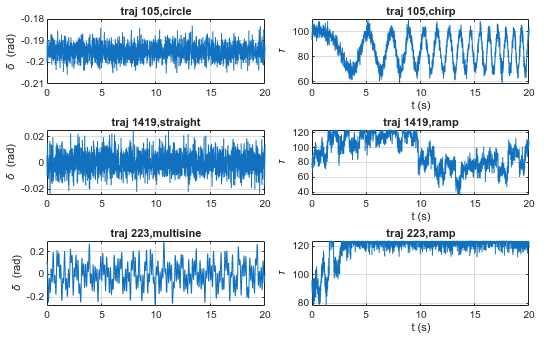


%% 4) Plot a few examples
idx = randperm(n_traj, 3);
figure('Color','w'); tiledlayout(3,2,'TileSpacing','compact','Padding','compact');
for j=1:numel(idx)
    k = idx(j);
    nexttile; plot(t, DELTA(:,k)); grid on; ylabel('\delta (rad)'); title(sprintf('traj %d,%s',k,traj_name(1,k)));
    nexttile; plot(t, TAU(:,k));   grid on; ylabel('\tau'); xlabel('t (s)');title(sprintf('traj %d,%s',k,traj_name(2,k)));
end


%% --------- helpers ----------
function y = multiSine(t, w, A, phi)
    y = zeros(numel(t),1);
    for i=1:numel(w), y = y + A(i)*sin(w(i)*t + phi(i)); end
end
function a = pickAmps(rngPerTone, J, totalCap)
    a = rngPerTone(1) + (rngPerTone(2)-rngPerTone(1))*rand(1,J);
    if sum(a) > totalCap, a = a * (totalCap/sum(a)); end
end
function f = pickTones(pool, J)
    f = datasample(pool, J, 'Replace', false);
end
function f = pickTonesDisjoint(pool, J, pool_other, Jother)
    f = datasample(pool, J, 'Replace', false);
    % very light disjointness guard (already different pools, but keep it)
    % could expand with min-separation constraints if you want
end
function x = saturate(x, lim), x = min(max(x, -lim), lim); end
function v = randRange(rng2), v = rng2(1) + (rng2(2)-rng2(1))*rand; end
function [y, segs] = rampAccelDecel(t, bias, R, Tmax)
% RAMPACCELDECEL  Piecewise-linear accel/decel with PE overlays.
% Keeps the original "ramp" intent (accel/decel segments), but adds:
%   • High-freq multisine (0.6–2.0 Hz) → ≥3–10 cycles per 5 s window.
%   • Small PRBS overlay (independent steps).
%   • Tiny white dither.
% Signature stays the same as your old function.

    % --- base piecewise-linear ramp around 'bias' ---
    N  = numel(t); t = t(:); y = bias*ones(N,1);
    nseg = randi([3,5]);                    % more segments → more variety
    segs = zeros(nseg,3);                   % [t0, t1, slope]
    t0 = t(1); i0 = 1;

    for s = 1:nseg
        if i0 >= N, break; end
        % duration in [R.segDur(1), R.segDur(2)] (seconds)
        dur = R.segDur(1) + (R.segDur(2)-R.segDur(1))*rand;
        t1  = min(t0 + dur, t(end));
        % slope in ±[R.slope(1), R.slope(2)] * Tmax per second
        sgn   = (rand>0.5)*2 - 1;
        slope = sgn * (R.slope(1) + (R.slope(2)-R.slope(1))*rand) * Tmax;

        % indices for this segment [i0 .. i1]
        i1 = find(t <= t1, 1, 'last');
        y(i0:i1) = y(i0) + slope*(t(i0:i1) - t0);   % linear ramp
        if i1 < N, y(i1+1:end) = y(i1); end        % hold to next segment

        segs(s,:) = [t0, t1, slope];
        t0 = t(i1); i0 = i1;                        % next segment starts here
    end

    % --- PE overlays (small, safe) ---
    % 1) High-freq multisine (disjoint from typical steering low rates)
    hfHz = linspace(0.6, 2.0, 12);                  % Hz (ensures cycles in 5 s)
    Jhf  = randi([2,4]);                            % 2–4 tones
    idx  = randperm(numel(hfHz), Jhf);
    w    = 2*pi*hfHz(idx);
    phi  = 2*pi*rand(1,Jhf);
    % total overlay amplitude ~ 5–10% of Tmax
    Atot = (0.05 + 0.05*rand) * Tmax;
    A    = Atot * (rand(1,Jhf)); A = A * (Atot/sum(A));  % split safe
    y = y + multiSine(t, w, A, phi);

    % 2) Small PRBS overlay (broadband edges)
    prbsAmp = (0.05 + 0.10*rand) * Tmax;            % 5–15% of Tmax
    dwell   = 0.20 + 0.40*rand;                     % 0.20–0.60 s
    y = y + prbsSignal(t, prbsAmp, dwell);

    % 3) Tiny white dither
    dRMS = (0.01 + 0.02*rand) * Tmax;               % 1–3% of Tmax
    y = y + dRMS*randn(N,1);

    % --- hard limits (time-only, not state-dependent) ---
    y = min(max(y, 0), 0.95*Tmax);
end

function y = fishhookSignal(t, A, rise, t1, t2)
% FISHHOOK: 0→A with smooth rise starting at t1, then A→-A starting at t2.
% Uses a cubic smoothstep to avoid corners.
    s1 = smoothstep01(t, t1, rise);   % 0→1 starting at t1
    s2 = smoothstep01(t, t2, rise);   % 0→1 starting at t2
    y  = A*( s1 - 2*s2 );             % 0→A, then A→-A
end

function s = smoothstep01(t, t0, tr)
% 0 before t0, 1 after t0+tr, cubic (C1) in between.
    tr = max(tr, eps);
    x = (t - t0)./tr;
    s = zeros(size(t));
    i1 = x >= 1;  s(i1) = 1;
    i0 = x <= 0;  % already zero
    im = ~(i1|i0);
    xx = x(im);
    s(im) = xx.^2 .* (3 - 2*xx);      % 3x^2 - 2x^3
end

function u = prbsSignal(t, lvl, dwell)
    u = zeros(size(t));
    hold = max(1, round(dwell/(t(2)-t(1))));
    s = 0;
    for k=1:numel(t)
        if mod(k,hold)==1, s = lvl*sign(randn); end
        u(k) = s;
    end
end
function H = block_hankel(x, nu)
    if isvector(x), x = x(:); end
    [N, r] = size(x); T = N - nu + 1;
    H = zeros(r*nu, T);
    for i=1:nu, H((i-1)*r+(1:r), :) = x(i:(i+T-1), :).'; end
end
